clc; close all; clear all;
tic;

## Confidence intervals

*For this week we will be using the real data you are working on, but more as a background for the main activity rather than in depth explorations.*

**Setup:**

*First, we want to have some `background' data (presumably signal free) onto which we can inject a simulated signal. So the first step is to isolate some appropriate data from your data files. *

*LHC*

*For the LHC data, we are going to have to fake a background. Make a Poisson background with mean 100. *

**Problem 1**

*The first problem is to look at your background distribution and determine where the 5σ sensitivity threshold is. [Hint, you've done this several times now, look back at the first few labs.]*

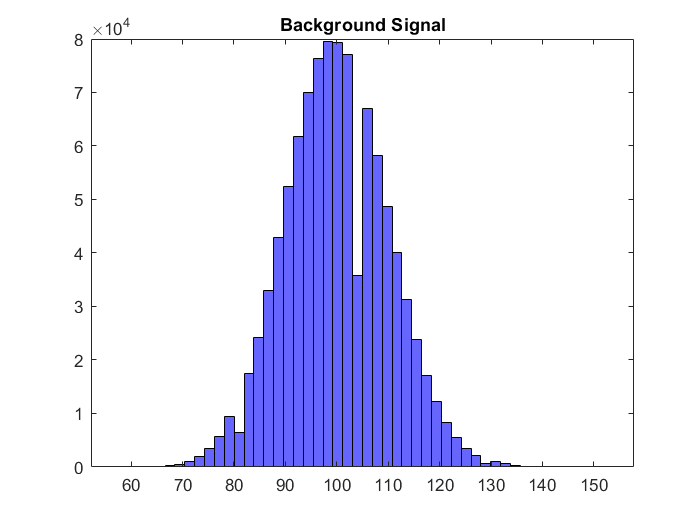

lambda = 100;
x = 1:1000000;
for i= 1:length(x)
    noise(i) = poissrnd(lambda);
end
histogram(noise, 50,"FaceColor",[0 0 1])
title('Background Signal')

sig = std(noise)

sig = 9.9882

sigma5 = 5*sig

sigma5 = 49.9410

5 sigma threshhold is from approximately [50,150].

**Problem 2**

*Now create a set of injected (simulated) signals of a single strength. You will want to make your signal moderately strong, say somewhere in the 8-30σ range. Inject this signal into your background data many times.*

*a) Histogram how bright the observed signal appears to be, and discuss it's shape. Say in words what this histogram is telling you.*

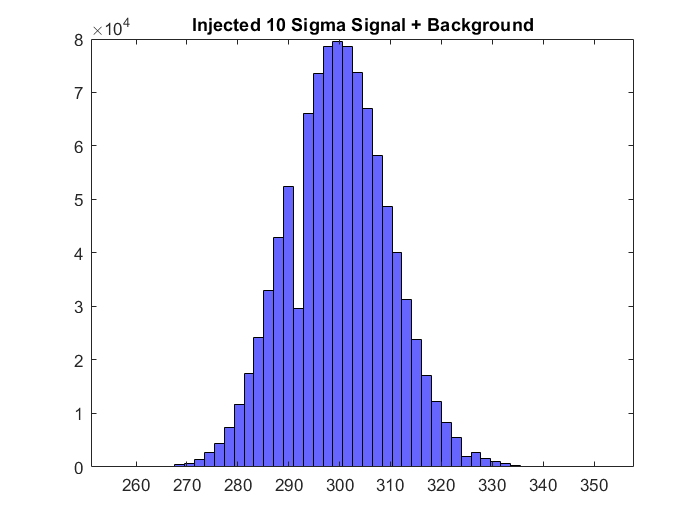

m(1) = 0;
for i=1:1000000
    m(i)=noise(i) + (lambda+10*sig);
end
histogram(m, 50,"FaceColor", [0 0 1])
title('Injected 10 Sigma Signal + Background')

After adding the injected signal, the median (lambda value) increased by about 200 to a new value of 300 because of the injected signal. It retains a Poisson distribution after adding the injected signal because the background noise is also a Poisson distribution.

*b) Is your observed signal biased? (e.g. is the observed value equally likely to be stronger or weaker than the true injected signal?) Is it symmetric?*

The observed signal is more likely to be stronger than the true injected signal because within the observed signal, we see the background noise added on top of the true signal's values therefore skewing the distribution towards the right by a median value of 200. It is not symmetric because neither the noise nor the injected signal is symmetrical however both sides of the graph relative to the median do look similar, as it should since it is a Poisson distribution.

**Problem 3**

*Now make a suite of injected signals. You will want to have a range of injected signal strengths, starting at zero and extending well above 5σ (30σ or more). *

*a) Clearly state what you are simulating, and make a 2D histogram of injected signal vs. observed signal*

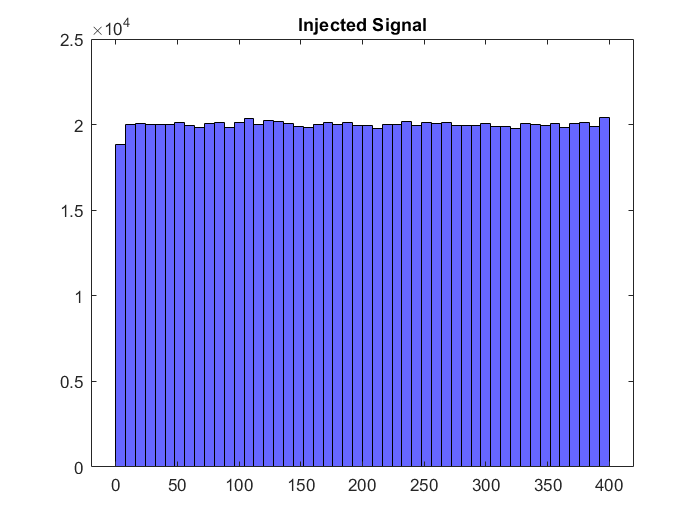

for i = 1:1000000
    injectedSignal(i) = round(40*sig*rand(1));
end
histogram(injectedSignal, 50, "FaceColor",[0 0 1])
title ('Injected Signal')

Here I injected a signal where the distribution spans from 0 to the 40 Sigma value of problem 1.

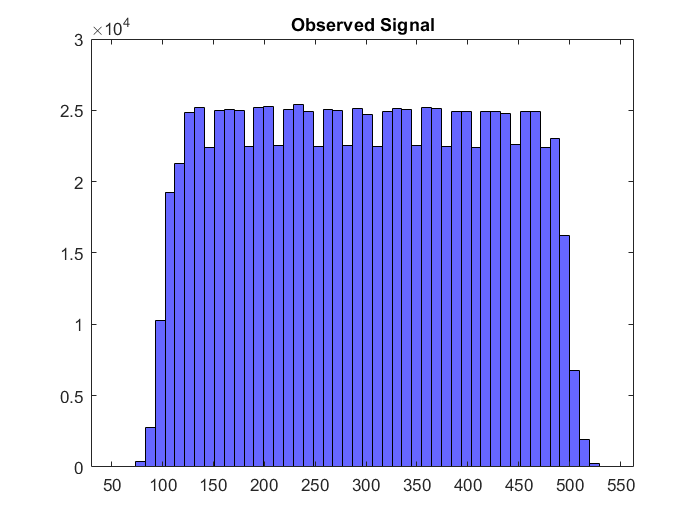

observedSignal = noise+injectedSignal;
histogram(observedSignal,50,"FaceColor",[0 0 1])
title 'Observed Signal'

Observed signal is the combination of the background noise and the injected signal. The observed signal is equivalent to adding the background noise to the injected signal. Looking at the histogram of the Observed signal, we see that there aren't many values lower than 100 and virtually none lower than 75. This is because the background noise has an average value of 100 and thus it shifts the graph by 100 to the right. We see something similar at the high end of the graph where it tapers off just after 500, which is 100 more than the maximum possible injected signal value and this is also caused by the addition of the background noise.

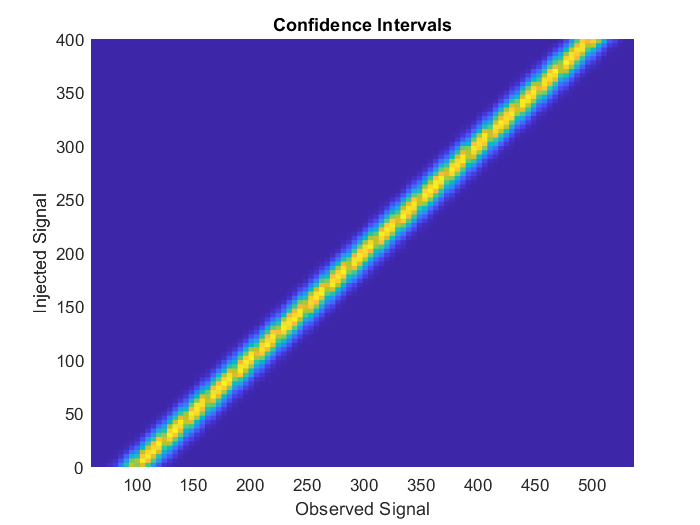

histogram2(observedSignal, injectedSignal,100,'DisplayStyle','tile','ShowEmptyBins','on')
xlabel 'Observed Signal'
ylabel 'Injected Signal'
title 'Confidence Intervals'

Plotting the 2D histogram injected signal v.s. observed signal, we see that the observed signal is directly proportional to the injected signal. The equation for the value of the injected signal seems to be inj = observed signal (variable) - background noise (variable within a range of values where the background noise has an average value of 100).

*b) If you choose the same injected signal power as in problem 2, show that you get the same answer.*

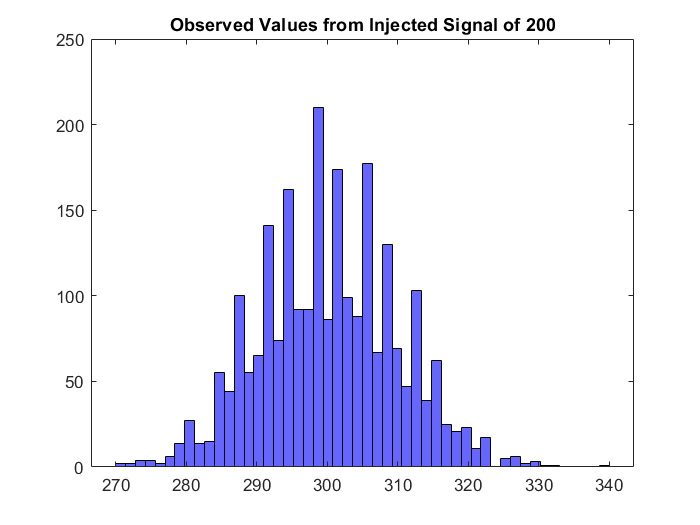

y(1)=0;
for i = 1:1000000
    if injectedSignal(i) == 200
        y = [y ,observedSignal(i)];
    end
end
y = y(2:length(y)); % We're excluding the first value because we arbitrarily picked a value for it.
histogram(y, 50, "FaceColor", [0 0 1])
title('Observed Values from Injected Signal of 200')

The observed signal is going to be similar to the one used in problem 2. By finding all the indices that have an injected signal of 200, we're performing a similar action to slicing the 2D histogram shown above at Injected Signal = 200. The resulting histogram is similar to problem 2 where we injected 10 sigma signals with the median for both being at about 300.

*c) Now reverse the problem, select an observed signal (pick something quite a bit stronger than 5σ) and create a 1D histogram of the injected signal pdf(). Describe the meaning of this histogram.*

z(1)=0;
signal = round(20*sig + lambda + mean(noise))

signal = 400

for i = 1:1000000
    if observedSignal(i) == signal
        z = [z ,injectedSignal(i)];
    end
end
avgSignal = mean(z(2:length(z)))

avgSignal = 300.0447

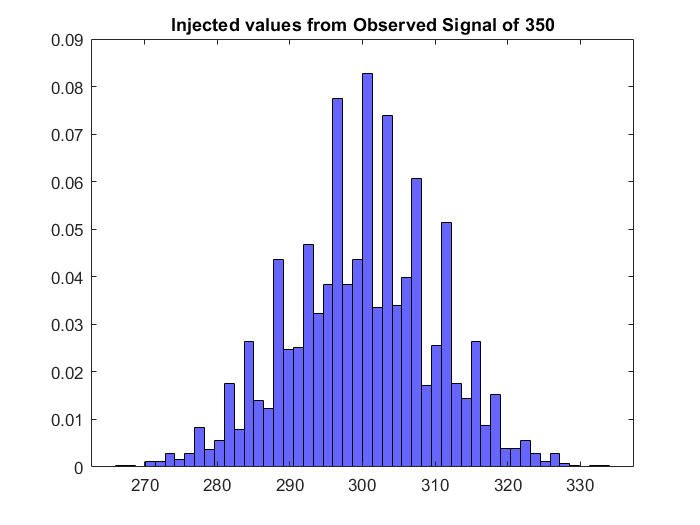

z = z(2:length(z)); % We're excluding the first value because we arbitrarily picked a value for it.
histogram(z, 50, 'Normalization', 'Probability', "FaceColor", [0 0 1])
title('Injected values from Observed Signal of 350')

Using a value of 20Sigma + average background noise + the median of the observed signal, we get a value of approximately 400 for the signal. Slicing the 2D histogram once again yields the above graph. This time we see a mean of approximately 250, which makes sense since the background noise has an average value of 100.

*d) For your observed signal, what is the 1σ uncertainty on the true signal strength?*

1σ uncertainty is the range of values that are considered to be basically guarenteed to have been made by signals.

avgSignal

avgSignal = 300.0447

sigma = std(z(2:length(z)))

sigma = 10.0364

acceptableRange = [avgSignal-sigma,avgSignal+sigma]

acceptableRange =   290.0083  310.0811


*e) Discuss the answer to part d in some depth. Is it symmetric? Is it biased? Does this make sense?*

It is not symmetric because there are more values between 300 and 210 than there are between 290 and 300. I don't beleive it is biased necesarily because this is just how the data ended up looking. It makes some sense because if this were continous it would look fairly Gaussian however this is a dicontinuous Poisson distribution and therefore the standard deviation doesn't neccesarily mean the same thing in this context.

**Problem 4**

*Using the same setup as in problem 3, now pick a relatively weak signal (say in the 1σ range, exact strength not important).*

*a) Repeat problem 3c, calculating the injected signal pdf(). One of the differences you should immediately see is that the pdf() extends to zero.*

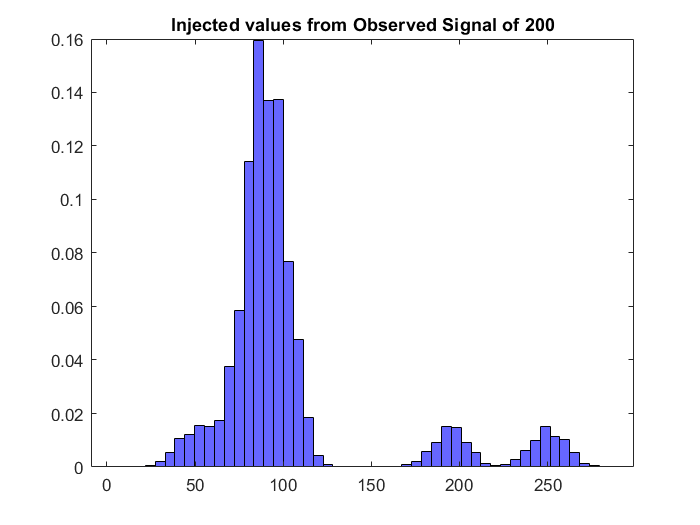

k(1)=0;
for i = 1:1000000
    if observedSignal(i) == 295 %within 1Sigma
        k = [k ,injectedSignal(i)];
    end
end
k = k(2:length(k)); %arbitrarily assigned once again....
histogram(k, 50, 'Normalization','Probability',"FaceColor", [0 0 1])
title('Injected values from Observed Signal of 200')

*b) Describe what it means to have the true signal pdf() extend to zero.*

If the true signal pdf extends to zero, there is a chance that the signal was actually produced entirely by the background noise since the observed signal is made from the addition of the background noise to the true signal.

*c) Calculate a 95% confidence upper bound. [Hints: make sure your pdf() is normalized. The statistical question is:  if I observe this candidate signal (and it is too weak to claim a detection), then the true signal would be less than X 95% of the time.]*

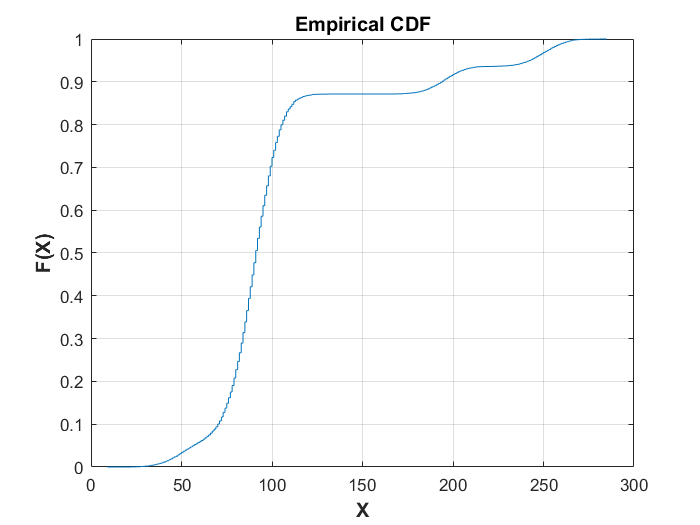

cdfplot(k);

It looks like the 95% confidence upper bound is about 200, in which case, if a given candidate signal is too weak for a valid detection, then the true signal is less than 200 95% of the time.

toc

Elapsed time is 124.781148 seconds.


function cdfplot(X)
% cdfplot(X) 
% displays a plot of the Empirical Cumulative Distribution Function 
% (CDF) of the input array X in the current figure. The empirical 
% CDF y=F(x) is defined as the proportion of X values less than or equal to x.
% If input X is a matrix, then cdfplot(X) parses it to the vector and 
% displays CDF of all values.
%
% EXAMPLE:
% figure;
% cdfplot(randn(1,100));
% hold on;
% cdfplot(-log(1-rand(1,100)));
% cdfplot(sqrt(randn(1,100).^2 + randn(1,100).^2))
% legend('Normal(0,1) CDF', 'Exponential(1) CDF', 'Rayleigh(1) CDF', 4)
% Version 1.0
% Alex Podgaetsky, September 2003
% alex@wavion.co.il
%
% Revisions:
%       Version 1.0 -   initial version
tmp = sort(reshape(X,prod(size(X)),1));
Xplot = reshape([tmp tmp].',2*length(tmp),1);
tmp = [1:length(X)].'/length(X);
Yplot = reshape([tmp tmp].',2*length(tmp),1);
Yplot = [0; Yplot(1:(end-1))];
figure(gcf);
hp = plot(Xplot, Yplot);
ColOrd = get(gca, 'ColorOrder'); 
ord = mod(length(get(gca,'Children')), size(ColOrd,1)); 
set(hp, 'Color', ColOrd((ord==0) + (ord>0)*ord, :));
if ~ishold
     xlabel('X', 'FontWeight','b','FontSize',12);
     ylabel('F(X)', 'FontWeight','b','FontSize',12);
     title('Empirical CDF', 'FontWeight','b','FontSize',12);
     grid on;
end
end